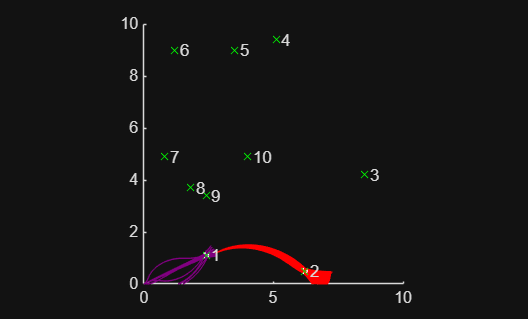

% monte carlo simulation for ma433 final project

% problem setup
cities = [8.5, 6.2, 3.5, 5.1, 4.0, 0.8, 2.4, 1.2, 1.8, 2.4; 4.2, 0.5, 9.0, 9.4, 4.9, 4.9, 3.4, 9.0, 3.7, 1.1];
corners = [0, 10, 10, 0; 0, 0, 10, 10];
sequence = [1, 10, 2, 1, 4, 3, 8, 6, 9, 7, 5];

% arc parameters to tune
A = [1, 1, 1, 1, 1, 1, 1, 1, 1, 1]; % mean acceleration for each arc
C = [0, 0, 0, 0, 0, 0, 0, 0, 0, 0]; % number of surviving trajectories after each arc
G = [1, -1, 1, 1, 1, 1, 1, 1, 1, 1]; % starting turning direction
M = 101; % number of points to integrate over
N = [1000, 100, 100, 100, 100, 100, 100, 100, 100, 100]; % number of offspring each survivor creates
R = [0.1, 0.1, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5, 0.5]; % tolerance for reaching the city
T = [2.5, 1.5, 2, 2, 2, 2, 2, 2, 2, 2]; % time allotted to reach the city in
K = 2; % number of cities checking to

% initialize plot
figure()
hold on;
axis equal;
axis([0 10 0 10])


% check up to K cities:
x0 = corners(1, sequence(1));
y0 = corners(2, sequence(1));
v0 = 0;
theta0 = normrnd(atan2(cities(2, sequence(2))-y0, cities(1, sequence(2))-x0), 0.1);
ICs = [x0; y0; v0; theta0];
c = 1;
for i = 1:K
    [ICs, c] = montecarlo(ICs, A(i), c, G(i), M, N(i), R(i), T(i), cities(:, sequence(i+1)), [i/K, 0, 1-i/K]);
    C(i) = c;
end

% postproc - plot cities and tolerance circles
scatter(cities(1, :), cities(2, :), 'xg');
for i = 1:10
    text(cities(1, sequence(i+1)) + 0.2, cities(2, sequence(i+1)), num2str(i))
end
angle = linspace(0, 2*pi, 25);
for i = 1:K
    x = R(i)*cos(angle) + cities(1, sequence(i+1));
    y = R(i)*sin(angle) + cities(2, sequence(i+1));
    plot(x, y, ':w')
end


% monte carlo function
function [newICs, newC] = montecarlo(ICs, a0, c, g0, m, n, r, t, target, color)
    tspan = linspace(0, t, m);
    count = 0;

    for h = 1:c
        for i = 1:n
            % generate a and gamma vectors to pass in to odes:
            num_ts = round(rand() * 3); % random number between 0 and 3, weighted towards 1.5
            ts = 0;
            for j = 1:num_ts
                ts(j) = tspan(ceil(rand() * m)); % random switching time between 0 and t
            end
            g = ones(1, m);
            a = zeros(1, m);
            for j = 1:m
                if (any(ismember(ts, tspan(j))))
                    g0 = floor(rand() * 3) - 1; % set steering to either left, right, or straight
                end
                g(j) = g0;
                a(j) = min(1, max(-1, normrnd(a0, 0.1))); % let acceleration vary slightly, saturate to -1<=a<=1
            end
        
            % integrate trajectory over given timespan
            [~, S] = ode45(@(t, s)ODEs(t, s, a, g, tspan), tspan, ICs(:, c));
            
            % filter out and save paths that reach the target in the given time
            dist = (S(:, 1) - target(1)).^2 + (S(:, 2) - target(2)).^2;
            if min(dist) < r^2
                count = count + 1;
                sols(:, count) = S(end, :);
                plot(S(:,  1), S(:, 2), 'Color', color)
            end
        end
    end
    if (count < 1)
        newICs = NaN;
    else
        newICs = sols;
    end
    newC = count;
end
function ds = ODEs(t, s, a, g, tspan)
    idx = 1;
    while(t > tspan(idx))
        idx = idx + 1;
    end
    ds(1, 1) = s(3)*cos(s(4)); % xdot = v*cos(theta)
    ds(2, 1) = s(3)*sin(s(4)); % ydot = v*sin(theta)
    ds(3, 1) = a(idx); % vdot = a
    ds(4, 1) = g(idx); % thetadot = gamma
end